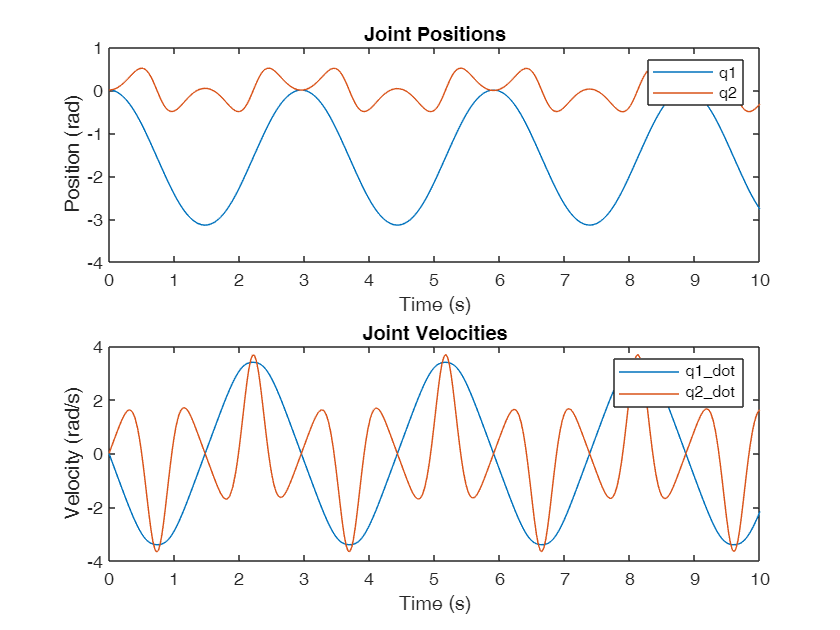


% Define system parameters
m1 = 1; m2 = 0.1;   % masses of the links
l1 = 1.5; l2 = 0.5;   % lengths of the links
g = 9.81;         % gravity

% Initial conditions [q1, q2, q1_dot, q2_dot]
q0 = [0; 0];      % initial positions (rad)
q_dot0 = [0; 0];  % initial velocities (rad/s)
y0 = [q0; q_dot0];

% Time span
tspan = [0 10];   % simulate for 10 seconds

% Integrate the system
[t, y] = ode45(@(t, y) dynamics(t, y, m1, m2, l1, l2, g), tspan, y0);

% Plot results
figure;
subplot(2,1,1);
plot(t, y(:,1:2)); % joint angles
title('Joint Positions');
xlabel('Time (s)');
ylabel('Position (rad)');
legend('q1', 'q2');

subplot(2,1,2);
plot(t, y(:,3:4)); % joint velocities
title('Joint Velocities');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend('q1\_dot', 'q2\_dot');

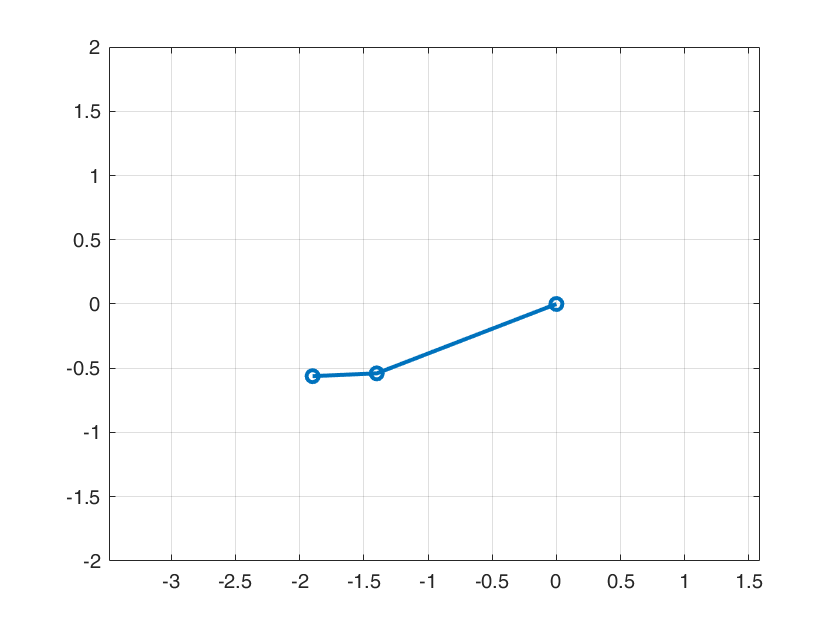

figure;
for i = 1:numel(t)  % Correct the loop to iterate over all time steps
    % Calculate the position of the first joint
    x1 = l1 * cos(y(i, 1));
    y1 = l1 * sin(y(i, 1));
    
    % Calculate the position of the end-effector (second joint)
    x2 = x1 + l2 * cos(y(i, 1) + y(i, 2));
    y2 = y1 + l2 * sin(y(i, 1) + y(i, 2));
    
    clf;

    % Plot the links
    plot([0, x1, x2], [0, y1, y2], 'o-', 'LineWidth', 2);
    axis([-2, 2, -2, 2]);  % Set axis limits
    axis equal;            % Keep aspect ratio consistent
    grid on;

    % Pause to create the animation effect
    pause(0.01);
end

function dydt = dynamics(~, y, m1, m2, l1, l2, g)
    % Extract positions and velocities
    q1 = y(1); q2 = y(2);
    q1_dot = y(3); q2_dot = y(4);

    % Inertia matrix D(q)
    D11 = m1*l1^2 + m2*(l1^2 + l2^2 + 2*l1*l2*cos(q2));
    D12 = m2*(l2^2 + l1*l2*cos(q2));
    D21 = D12;
    D22 = m2*l2^2;
    D = [D11, D12; D21, D22];

    % Coriolis and centrifugal matrix C(q, q_dot)
    C11 = -m2*l1*l2*sin(q2)*q2_dot;
    C12 = -m2*l1*l2*sin(q2)*(q1_dot + q2_dot);
    C21 = m2*l1*l2*sin(q2)*q1_dot;
    C22 = 0;
    C = [C11, C12; C21, C22];

    % Gravity vector G(q)
    G1 = (m1*l1 + m2*l1)*g*cos(q1) + m2*l2*g*cos(q1 + q2);
    G2 = m2*l2*g*cos(q1 + q2);
    G = [G1; G2];

    % Input torque (for example purposes)
    tau = [0; 0]; % No input torque, simulate free fall

    % Compute accelerations
    q_double_dot = D \ (tau - C * [q1_dot; q2_dot] - G);

    % Return the derivative of the state
    dydt = [q1_dot; q2_dot; q_double_dot];
end
